% Step 1: Generate points near the six faces of a cube
num_points = 100; % Number of points per face
side_length = 1; % Side length of the cube
epsilon = 0.01; % Small perturbation

% Initialize arrays for each face
face1 = zeros(num_points, 3);
face2 = zeros(num_points, 3);
face3 = zeros(num_points, 3);
face4 = zeros(num_points, 3);
face5 = zeros(num_points, 3);
face6 = zeros(num_points, 3);

% Generate points for each face
for i = 1:num_points
    % Front face (z = side_length/2)
    face1(i, :) = [side_length * (rand() - 0.5), side_length * (rand() - 0.5), side_length/2 + epsilon * (rand() - 0.5)];
    
    % Back face (z = -side_length/2)
    face2(i, :) = [side_length * (rand() - 0.5), side_length * (rand() - 0.5), -side_length/2 + epsilon * (rand() - 0.5)];
    
    % Left face (x = -side_length/2)
    face3(i, :) = [-side_length/2 + epsilon * (rand() - 0.5), side_length * (rand() - 0.5), side_length * (rand() - 0.5)];
    
    % Right face (x = side_length/2)
    face4(i, :) = [side_length/2 + epsilon * (rand() - 0.5), side_length * (rand() - 0.5), side_length * (rand() - 0.5)];
    
    % Top face (y = side_length/2)
    face5(i, :) = [side_length * (rand() - 0.5), side_length/2 + epsilon * (rand() - 0.5), side_length * (rand() - 0.5)];
    
    % Bottom face (y = -side_length/2)
    face6(i, :) = [side_length * (rand() - 0.5), -side_length/2 + epsilon * (rand() - 0.5), side_length * (rand() - 0.5)];
end

% Step 2: Combine all points into a single array for visualization
points = [face1; face2; face3; face4; face5; face6];

% Step 3: Define rotation and translation
theta = pi/6; % Rotation angle
R = [cos(theta) -sin(theta) 0;
     sin(theta) cos(theta) 0;
     0 0 1]; % Rotation matrix around z-axis
T = [0.1, 0.1, 0.1]; % Translation vector

% Apply rotation and translation
points_rot_trans = (R * points')' + T;

% Step 4: Extract the new coordinates for each face
face1_transformed = points_rot_trans(1:num_points, :);
face2_transformed = points_rot_trans(num_points+1:2*num_points, :);
face3_transformed = points_rot_trans(2*num_points+1:3*num_points, :);
face4_transformed = points_rot_trans(3*num_points+1:4*num_points, :);
face5_transformed = points_rot_trans(4*num_points+1:5*num_points, :);
face6_transformed = points_rot_trans(5*num_points+1:6*num_points, :);

% Step 5: Save the plane parameters for each face
% Plane equation: ax + by + cz = d
planes = zeros(6, 4);

% Fit planes to each face
fit_options = fitoptions('poly11');
fit_type = fittype('poly11');

% Front face
f_front = fit([face1_transformed(:, 1), face1_transformed(:, 2)], face1_transformed(:, 3), fit_type, fit_options);
planes(1, :) = [f_front.p10, f_front.p01, -1, f_front.p00];

% Back face
f_back = fit([face2_transformed(:, 1), face2_transformed(:, 2)], face2_transformed(:, 3), fit_type, fit_options);
planes(2, :) = [f_back.p10, f_back.p01, -1, f_back.p00];

% Left face (x = -side_length/2)
f_left = fit([face3_transformed(:, 2), face3_transformed(:, 3)], face3_transformed(:, 1), fit_type, fit_options);
planes(3, :) = [-1, f_left.p10, f_left.p01, f_left.p00];

% Right face (x = side_length/2)
f_right = fit([face4_transformed(:, 2), face4_transformed(:, 3)], face4_transformed(:, 1), fit_type, fit_options);
planes(4, :) = [-1, f_right.p10, f_right.p01, f_right.p00];

% Top face (y = side_length/2)
f_top = fit([face5_transformed(:, 1), face5_transformed(:, 3)], face5_transformed(:, 2), fit_type, fit_options);
planes(5, :) = [f_top.p10, -1, f_top.p01, f_top.p00];

% Bottom face (y = -side_length/2)
f_bottom = fit([face6_transformed(:, 1), face6_transformed(:, 3)], face6_transformed(:, 2), fit_type, fit_options);
planes(6, :) = [f_bottom.p10, -1, f_bottom.p01, f_bottom.p00];

% Display the results
disp('Plane parameters (a, b, c, d) for each face:');

Plane parameters (a, b, c, d) for each face:


disp(planes);

    0.0009    0.0010   -1.0000    0.6002
    0.0006   -0.0005   -1.0000   -0.4003
   -1.0000   -0.5774   -0.0012   -0.4197
   -1.0000   -0.5746   -0.0013    0.7345
    0.5774   -1.0000   -0.0007    0.6191
    0.5770   -1.0000   -0.0004   -0.5349



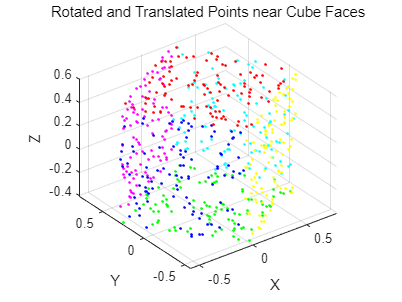


% Visualization
figure;
scatter3(face1_transformed(:,1), face1_transformed(:,2), face1_transformed(:,3), 'r.');
hold on;
scatter3(face2_transformed(:,1), face2_transformed(:,2), face2_transformed(:,3), 'g.');
scatter3(face3_transformed(:,1), face3_transformed(:,2), face3_transformed(:,3), 'b.');
scatter3(face4_transformed(:,1), face4_transformed(:,2), face4_transformed(:,3), 'c.');
scatter3(face5_transformed(:,1), face5_transformed(:,2), face5_transformed(:,3), 'm.');
scatter3(face6_transformed(:,1), face6_transformed(:,2), face6_transformed(:,3), 'y.');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Rotated and Translated Points near Cube Faces');
axis equal;
grid on;


face1_transformed = face1_transformed';
face2_transformed = face2_transformed';
face3_transformed = face3_transformed';
face4_transformed = face4_transformed';
face5_transformed = face5_transformed';
face6_transformed = face6_transformed';


BoundPoint1 = face5_transformed(:,10);
BoundPoint2 = face6_transformed(:,20);

save('PointFangXing.mat','planes',"face6_transformed","face5_transformed","face4_transformed","face3_transformed","face2_transformed","face1_transformed","BoundPoint1","BoundPoint2")